# Tarea2: Comparacion SNR algoritmo binary splitting

## a)

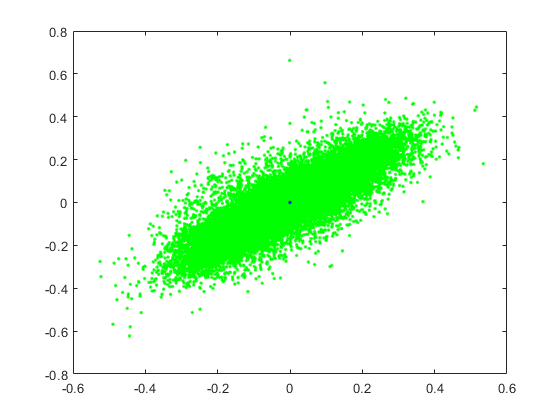

[data, fsdata] = audioread ('tvg_training_20s.wav');
training = ordename(data);

for i = 1 : 16
    t1 = clock;
    [VQ, vDist] = bsVQ (training, i, 0.025, 0.01, 1);
    t = etime(clock, t1)
    
    VQf (2^i-1 : 2*(2^i-1), :) = VQ;

    tf(i) = t;
    Distf(i) = length (vDist);
end

    
plot(tf)
title('Tiempo de la ejecución'); xlabel ('Numero de bits'); ylabel ('t[s]');
xlabel ('Número de Bits'), ylabel ('Tiempo ts(s)');

save ('VQf.mat', 'VQf', 'tf')

## b)

[s_5s fs_5s]= audioread ('tvg_training_5s.wav');
load VQf.mat VQf
matriz_training_5s= ordename(s_5s);




for i = 1 : 16
    Ini = 2^i - 1;
    Desp = 2^i - 1;
    
    VQ = VQf (Ini : Ini + Desp, :);
    
    [y1, ~] = VQuantize (matriz_training_5s, VQ);
    q = reshape (y1', [1 length(s_5s)]);
    QVQ (i, :) = q;
    
    
    [y2, e] = qmidriser (s_5s, 1, i);
    Qmr(i, :) = y2;
    
end




for z = 1 : 16
    SNRmr (z) = SNR (s_5s', Qmr(z, :));
end

for z = 1 : 16
    SNRVQ (z) = SNR (s_5s', QVQ (z, :));
end


n = 1 : 16;
Rbs = fs_5s .* n /1000;            % En kbps
RbsVQ = fs_5s .* n / 2 / 1000;      
SNRu = 6.02 .* n;               % SNR Uniforme
SNRn = 6.02 .* n - 7.27;        % SNR Normal

plot (Rbs,SNRu,'k', Rbs,SNRn,'g', RbsVQ,SNRVQ,'x-b', Rbs,SNRmr,'o-r'); ax = gca; ax.XTick = Rbs; grid
axis ([0 72 -10 60]);
title ('Comparacion SNR');
xlabel ('Rb (kbps)'); ylabel ('SNR (dB)');
legend ('Uniforme','Normal','VQ','Mid-riser');


[t_5s, ts_5s]= audioread ('tvg_test_5s.wav');
load VQf.mat VQf
matriz_training_5s= ordename(t_5s);




for i = 1 : 16
    Ini = 2^i - 1;
    Desp = 2^i - 1;
    
    VQ = VQf (Ini : Ini + Desp, :);
    
    [y1, ~] = VQuantize (matriz_training_5s, VQ);
    q = reshape (y1', [1 length(t_5s)]);
    QVQ2 (i, :) = q;
    
    
    [y2, e] = qmidriser (t_5s, 1, i);
    Qmr2(i, :) = y2;
    
end




for z = 1 : 16
    SNRmr2 (z) = SNR (s_5s', Qmr(z, :));
end

for z = 1 : 16
    SNRVQ2 (z) = SNR (s_5s', QVQ (z, :));
end


n = 1 : 16;
Rbs = fs_5s .* n /1000;            % En kbps
RbsVQ = fs_5s .* n / 2 / 1000;      
SNRu = 6.02 .* n;               % SNR Uniforme
SNRn = 6.02 .* n - 7.27;        % SNR Normal

plot (Rbs,SNRu,'k', Rbs,SNRn,'g', RbsVQ,SNRVQ,'x-b', Rbs,SNRmr,'o-r'); ax = gca; ax.XTick = Rbs; grid
axis ([0 72 -10 60]);
title ('Comparacion SNR');
xlabel ('Rb (kbps)'); ylabel ('SNR (dB)');
legend ('Uniforme','Normal','VQ','Mid-riser');

### d)

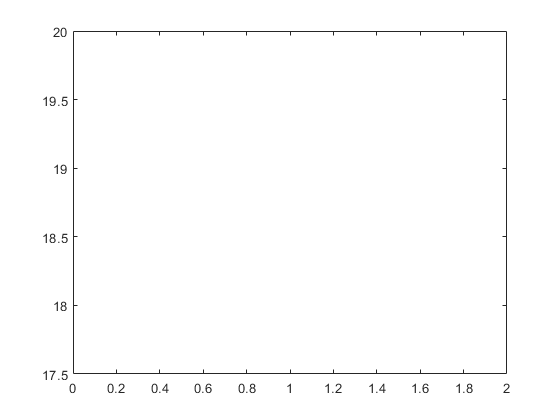

 [s20, fs20] = audioread ('tvg_training_20s.wav');




[VQ,vDist] = bsVQ(s20,5,0.025, 0.01, 0);


x=-1:0.0005:1;

[y20,dist20]=VQuantize(x',VQ);



[t_5s, ts_5s]= audioread ('tvg_test_5s.wav');
[s_5s, fs_5s]= audioread ('tvg_training_5s.wav');


 [t5,dist]=VQuantize(t_5s,VQ);
 t5snr=SNR(t_5s,t5);

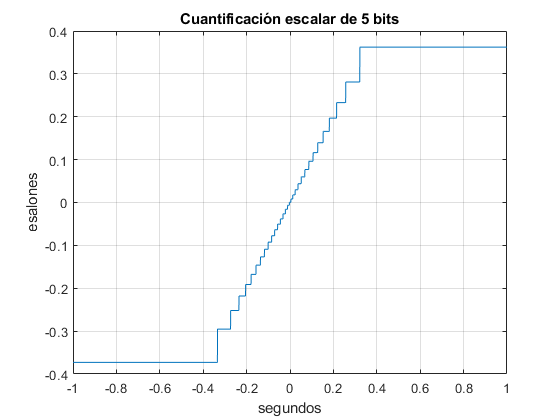

 [s5,dist]=VQuantize(s_5s,VQ);
 s5snr=SNR(s_5s,s5);

plot(x,y20); grid;
xlim([-1 1])
title(sprintf('Cuantificación escalar de 5 bits'));    
xlabel('segundos');  
ylabel('esalones');